# **Simulações de antenas *****microstrip***** com células SRR**

`por Renan Machado`

Este é um *live script* em MatLAB que visa construir um *dataset* de simulações de antenas para treinar modelos preditivos de *machine learning*. Os parâmetros das antenas, como largura e comprimento do *patch*, disposição das células SRR, e outros, serão variados em uma faixa de valores adequados, procurando respeitar as referências oferecidas pela literatura. O *software* utilizado para as simulações eletromagnéticas é o **CST Studio Lite©**, utilizando o módulo **Microwave Studio**. Para o controle automatizado do software, será utilizada a API desenvolvida por Symeon Symeonidis, Stefanos Tsantilas e Stelios Mitilineos, tendo o código fonte e a documentação disponíveis [aqui](https://github.com/simos421/CST-MATLAB-API).

## Inicialização do CST

Para correta utilização da API, antes é necessário adicionar seu código fonte ao *path*, dessa forma:

addpath(genpath('CST-MATLAB-API-master'));

Para iniciar a aplicação do CST, utilizamos o seguinte comando:

cst = actxserver('CSTStudio.application');

Agora, com o CST aberto, podemos inicializar o Microwave Studio.

mws = cst.invoke('NewMWS');

Você deve ter na sua tela algo parecido como a figura abaixo.

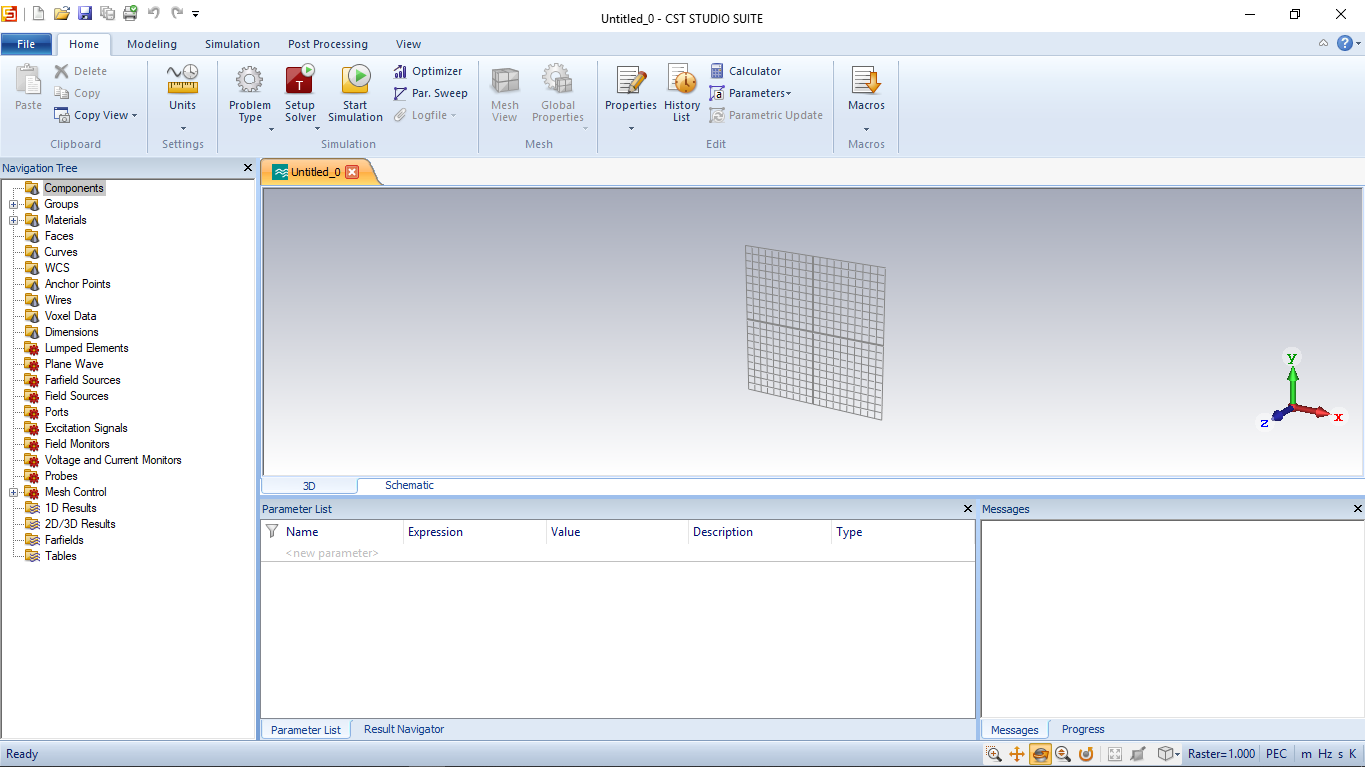

## Configurando o ambiente de simulação

Inicialmente, precisamos definir as unidades padrão. Com isso, também é necessário definir o intervalo de frequência que será simulado. Assim, é possível inicializar a *mesh* e definir as condições de contorno.

Aqui, a frequência será todo o domínio das bandas L, S, C, X, Ku e K, tendo o valor mínimo de 1GHz até 26,5 GHz.

fmin = 3;
%fmax = 26.5;
fmax = 4;

Em código:

CstDefineUnits(mws, 'mm', 'GHz', 's', 'Kelvin', 'V', 'A', 'Ohm', 'S', 'PikoF', 'NanoH');
CstDefineFrequencyRange(mws, fmin, fmax);
CstMeshInitiator(mws); 

A antena estará no espaço livre, então:

%Condições de contorno
Xmin = 'expanded open';
Xmax = 'expanded open';
Ymin = 'expanded open';
Ymax = 'expanded open';
Zmin = 'expanded open';
Zmax = 'expanded open';

CstDefineOpenBoundary(mws, fmin, Xmin, Xmax, Ymin, Ymax, Zmin, Zmax);

Em seguida, precisamos definir o material do fundo:

XminSpace = 0;
XmaxSpace = 0;
YminSpace = 0;
YmaxSpace = 0;
ZminSpace = 0;
ZmaxSpace = 0;

CstDefineBackroundMaterial(mws, XminSpace, XmaxSpace, YminSpace, YmaxSpace, ZminSpace, ZmaxSpace);

## Definição de materiais

Para a definição de materiais que serão utilizados nos componentes, é preciso definir as propriedades do material de acordo com a biblioteca do CST e fazer uma função em MatLAB com todas essas propriedades, juntamente com o nome do material. Somente depois disso é que podemos utilizar o nome do material no código. Na API, já temos funções para definir materiais como cobre e FR4 com perdas.

CstCopperAnnealedLossy(mws);
CstFR4lossy(mws);

materials_metalic = 'Copper (annealed)';
materials_dieletric = 'FR-4 (lossy)';

## Intervalo de valores para a antena

As variáveis associadas a geometria de uma antena *microstrip* são essas mostradas na figura abaixo. Alguns intervalos estão em função do comprimento de onda $\lambda$, de forma que:


$$\lambda =\frac{c}{f}$$


f_step = 50e-3;
f = fmin:f_step:fmax % in GHz (1e9 Hz)

f =     3.0000    3.0500    3.1000    3.1500    3.2000    3.2500    3.3000    3.3500    3.4000    3.4500    3.5000    3.5500    3.6000    3.6500    3.7000    3.7500    3.8000    3.8500    3.9000    3.9500    4.0000


lambda = 3e2./f % in mm (1e-3 m)

lambda =   100.0000   98.3607   96.7742   95.2381   93.7500   92.3077   90.9091   89.5522   88.2353   86.9565   85.7143   84.5070   83.3333   82.1918   81.0811   80.0000   78.9474   77.9221   76.9231   75.9494   75.0000


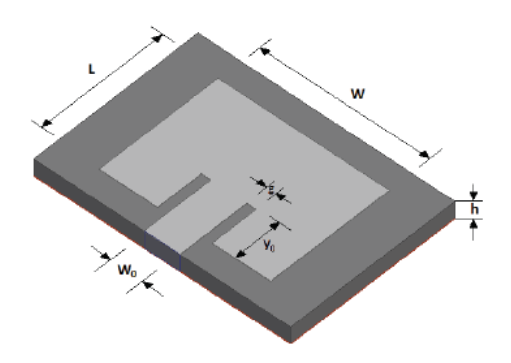

De acordo com a literatura, temos que:


$$0,003\lambda \;\le h\le 0,05\lambda$$



$$\frac{\lambda \;}{3}\le L\le 0,5\lambda$$



$$0,15\lambda \le W\le 0,5\lambda \;$$



$$0,2L\le Y_0 \le \frac{L}{3}$$



$$\frac{W}{6}\le W_0 \le 0,25W$$



$$0,2W_0 \le g\le 0,5W_0$$


hmin = 0.003;
hmax = 0.05;
h_step = hmin;

[h_factor, h] = GetAntennaValues(hmin, hmax, h_step, lambda)

h_factor =     0.0030    0.0060    0.0090    0.0120    0.0150    0.0180    0.0210    0.0240    0.0270    0.0300    0.0330    0.0360    0.0390    0.0420    0.0450    0.0480


h =     0.3000    0.2951    0.2903    0.2857    0.2813    0.2769    0.2727    0.2687    0.2647    0.2609    0.2571    0.2535    0.2500    0.2466    0.2432    0.2400    0.2368    0.2338    0.2308    0.2278    0.2250
    0.6000    0.5902    0.5806    0.5714    0.5625    0.5538    0.5455    0.5373    0.5294    0.5217    0.5143    0.5070    0.5000    0.4932    0.4865    0.4800    0.4737    0.4675    0.4615    0.4557    0.4500
    0.9000    0.8852    0.8710    0.8571    0.8438    0.8308    0.8182    0.8060    0.7941    0.7826    0.7714    0.7606    0.7500    0.7397    0.7297    0.7200    0.7105    0.7013    0.6923    0.6835    0.6750
    1.2000    1.1803    1.1613    1.1429    1.1250    1.1077    1.0909    1.0746    1.0588    1.0435    1.0286    1.0141    1.0000    0.9863    0.9730    0.9600    0.9474    0.9351    0.9231    0.9114    0.9000
    1.5000    1.4754    1.4516    1.4286    1.4063    1.3846    1.3636    1.3433    1.3235    1.3043    1.2857    1.2676    1.2500    1.2329    1.2162  

lmin = 1/3;
lmax = 1/2;
l_step = lmin/10;

[l_factor, l] = GetAntennaValues(lmin, lmax, l_step, lambda)

l_factor =     0.3333    0.3667    0.4000    0.4333    0.4667    0.5000


l =    33.3333   32.7869   32.2581   31.7460   31.2500   30.7692   30.3030   29.8507   29.4118   28.9855   28.5714   28.1690   27.7778   27.3973   27.0270   26.6667   26.3158   25.9740   25.6410   25.3165   25.0000
   36.6667   36.0656   35.4839   34.9206   34.3750   33.8462   33.3333   32.8358   32.3529   31.8841   31.4286   30.9859   30.5556   30.1370   29.7297   29.3333   28.9474   28.5714   28.2051   27.8481   27.5000
   40.0000   39.3443   38.7097   38.0952   37.5000   36.9231   36.3636   35.8209   35.2941   34.7826   34.2857   33.8028   33.3333   32.8767   32.4324   32.0000   31.5789   31.1688   30.7692   30.3797   30.0000
   43.3333   42.6230   41.9355   41.2698   40.6250   40.0000   39.3939   38.8060   38.2353   37.6812   37.1429   36.6197   36.1111   35.6164   35.1351   34.6667   34.2105   33.7662   33.3333   32.9114   32.5000
   46.6667   45.9016   45.1613   44.4444   43.7500   43.0769   42.4242   41.7910   41.1765   40.5797   40.0000   39.4366   38.8889   38.3562   37.8378  


wmin = 0.2;
wmax = 0.5;
w_step = wmin/10;

[w_factor, w] = GetAntennaValues(wmin, wmax, w_step, lambda)

w_factor =     0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000


w =    20.0000   19.6721   19.3548   19.0476   18.7500   18.4615   18.1818   17.9104   17.6471   17.3913   17.1429   16.9014   16.6667   16.4384   16.2162   16.0000   15.7895   15.5844   15.3846   15.1899   15.0000
   22.0000   21.6393   21.2903   20.9524   20.6250   20.3077   20.0000   19.7015   19.4118   19.1304   18.8571   18.5915   18.3333   18.0822   17.8378   17.6000   17.3684   17.1429   16.9231   16.7089   16.5000
   24.0000   23.6066   23.2258   22.8571   22.5000   22.1538   21.8182   21.4925   21.1765   20.8696   20.5714   20.2817   20.0000   19.7260   19.4595   19.2000   18.9474   18.7013   18.4615   18.2278   18.0000
   26.0000   25.5738   25.1613   24.7619   24.3750   24.0000   23.6364   23.2836   22.9412   22.6087   22.2857   21.9718   21.6667   21.3699   21.0811   20.8000   20.5263   20.2597   20.0000   19.7468   19.5000
   28.0000   27.5410   27.0968   26.6667   26.2500   25.8462   25.4545   25.0746   24.7059   24.3478   24.0000   23.6620   23.3333   23.0137   22.7027  

y0min = 0.2;
y0max = 1/3;
y0_step = (y0max - y0min)/(length(l_factor)-1);

[y0_factor, y0] = GetAntennaValues(y0min, y0max, y0_step, l)

y0_factor =     0.2000    0.2267    0.2533    0.2800    0.3067    0.3333


y0 =     6.6667    6.5574    6.4516    6.3492    6.2500    6.1538    6.0606    5.9701    5.8824    5.7971    5.7143    5.6338    5.5556    5.4795    5.4054    5.3333    5.2632    5.1948    5.1282    5.0633    5.0000
    8.3111    8.1749    8.0430    7.9153    7.7917    7.6718    7.5556    7.4428    7.3333    7.2271    7.1238    7.0235    6.9259    6.8311    6.7387    6.6489    6.5614    6.4762    6.3932    6.3122    6.2333
   10.1333    9.9672    9.8065    9.6508    9.5000    9.3538    9.2121    9.0746    8.9412    8.8116    8.6857    8.5634    8.4444    8.3288    8.2162    8.1067    8.0000    7.8961    7.7949    7.6962    7.6000
   12.1333   11.9344   11.7419   11.5556   11.3750   11.2000   11.0303   10.8657   10.7059   10.5507   10.4000   10.2535   10.1111    9.9726    9.8378    9.7067    9.5789    9.4545    9.3333    9.2152    9.1000
   14.3111   14.0765   13.8495   13.6296   13.4167   13.2103   13.0101   12.8159   12.6275   12.4444   12.2667   12.0939   11.9259   11.7626   11.6036 

w0min = 1/6;
w0max = 0.25;
w0_step = (w0max - w0min)/(length(w_factor)-1);

[w0_factor, w0] = GetAntennaValues(w0min, w0max, w0_step, w)

w0_factor =     0.1667    0.1722    0.1778    0.1833    0.1889    0.1944    0.2000    0.2056    0.2111    0.2167    0.2222    0.2278    0.2333    0.2389    0.2444    0.2500


w0 =     3.3333    3.2787    3.2258    3.1746    3.1250    3.0769    3.0303    2.9851    2.9412    2.8986    2.8571    2.8169    2.7778    2.7397    2.7027    2.6667    2.6316    2.5974    2.5641    2.5316    2.5000
    3.7889    3.7268    3.6667    3.6085    3.5521    3.4974    3.4444    3.3930    3.3431    3.2947    3.2476    3.2019    3.1574    3.1142    3.0721    3.0311    2.9912    2.9524    2.9145    2.8776    2.8417
    4.2667    4.1967    4.1290    4.0635    4.0000    3.9385    3.8788    3.8209    3.7647    3.7101    3.6571    3.6056    3.5556    3.5068    3.4595    3.4133    3.3684    3.3247    3.2821    3.2405    3.2000
    4.7667    4.6885    4.6129    4.5397    4.4688    4.4000    4.3333    4.2687    4.2059    4.1449    4.0857    4.0282    3.9722    3.9178    3.8649    3.8133    3.7632    3.7143    3.6667    3.6203    3.5750
    5.2889    5.2022    5.1183    5.0370    4.9583    4.8821    4.8081    4.7363    4.6667    4.5990    4.5333    4.4695    4.4074    4.3470    4.2883 

gmin = 0.2;
gmax = 0.5;
g_step = (gmax - gmin)/(length(w0_factor)-1);

[g_factor, g] = GetAntennaValues(gmin, gmax, g_step, w0)

g_factor =     0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000


g =     0.6667    0.6557    0.6452    0.6349    0.6250    0.6154    0.6061    0.5970    0.5882    0.5797    0.5714    0.5634    0.5556    0.5479    0.5405    0.5333    0.5263    0.5195    0.5128    0.5063    0.5000
    0.8336    0.8199    0.8067    0.7939    0.7815    0.7694    0.7578    0.7465    0.7355    0.7248    0.7145    0.7044    0.6946    0.6851    0.6759    0.6668    0.6581    0.6495    0.6412    0.6331    0.6252
    1.0240    1.0072    0.9910    0.9752    0.9600    0.9452    0.9309    0.9170    0.9035    0.8904    0.8777    0.8654    0.8533    0.8416    0.8303    0.8192    0.8084    0.7979    0.7877    0.7777    0.7680
    1.2393    1.2190    1.1994    1.1803    1.1619    1.1440    1.1267    1.1099    1.0935    1.0777    1.0623    1.0473    1.0328    1.0186    1.0049    0.9915    0.9784    0.9657    0.9533    0.9413    0.9295
    1.4809    1.4566    1.4331    1.4104    1.3883    1.3670    1.3463    1.3262    1.3067    1.2877    1.2693    1.2515    1.2341    1.2172    1.2007  

Vamos transformar todos os parâmetros que estão em forma de matriz em um array linear através da função *Flat.*

h = Flat(h);
l = Flat(l);
w = Flat(w);
y0 = Flat(y0);
w0 = Flat(w0);
g = Flat(g);

## Intervalo de valores para as células SRR

% TODO